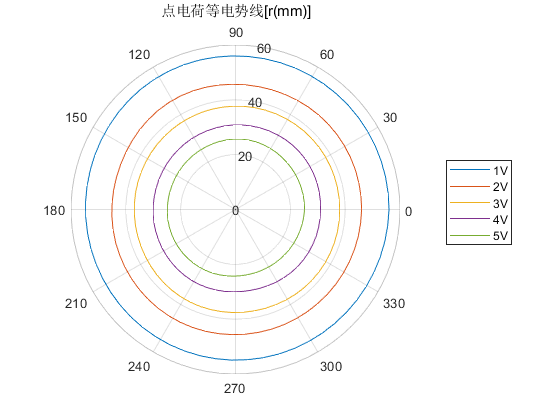

theta_data=linspace(0,2*pi,10);

r=zeros(5,10);
r(1,:)=[23,23,23,23,22.5,22.3,22.4,22.5,22.6,23];
r(2,:)=[18,18,17.8,18,17.5,17.7,17.9,17.8,17.8,18];
r(3,:)=[14,14,13.9,13.7,13.5,13.5,13.8,13.8,14,14];
r(4,:)=[10.5,10.7,10.5,10.2,10.0,10.1,10.2,10.0,10.4,10.5];
r(5,:)=[7.6,7.7,7.9,7.6,7.4,7.5,7.4,7.1,7.2,7.6];
r=r*2+10;
theta = linspace(0,2*pi,60); % 插值
r_1 = interp1(theta_data,r(1,:),theta,'cubic');
r_2 = interp1(theta_data,r(2,:),theta,'cubic');
r_3 = interp1(theta_data,r(3,:),theta,'cubic');
r_4 = interp1(theta_data,r(4,:),theta,'cubic');
r_5 = interp1(theta_data,r(5,:),theta,'cubic');
polarplot(theta,r_1,theta,r_2,theta,r_3,theta,r_4,theta,r_5)
title('点电荷等电势线[r(mm)]')
legend('1V','2V','3V','4V','5V')